% OCD = 300A
duty_cycle = [10 8 6 4 2 1]

duty_cycle =     10     8     6     4     2     1


i_rms_calc = [63.85 57.5 50.07 40.96 28.64 19.5];
i_rms_sim = [70.651 64.393 50.571 46.477 33.274 18.56];

percentError = 100 * abs(i_rms_calc - i_rms_sim) ./ i_rms_sim

percentError =     9.6262   10.7046    0.9907   11.8704   13.9268    5.0647



signedPercentError = ((i_rms_calc - i_rms_sim) ./ i_rms_sim)*100

signedPercentError =    -9.6262  -10.7046   -0.9907  -11.8704  -13.9268    5.0647


mspe = mean(signedPercentError) % Mean signed percent error (MSPE)

mspe = -7.0090

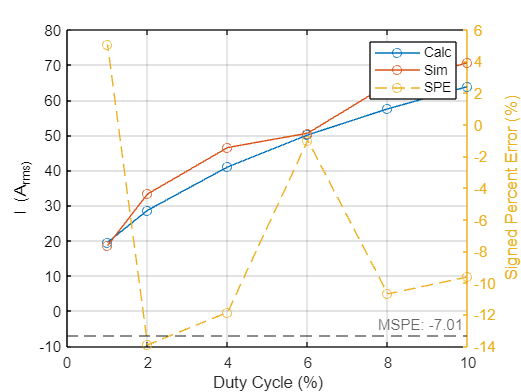

pe_mean = mean(percentError);

figure();
plot(duty_cycle,i_rms_calc,'-o');
hold on;
xlabel('Duty Cycle (%)');
ylabel('I (A_rms)');
plot(duty_cycle,i_rms_sim,'-o');
hold on;

% Switch to the right y-axis and plot
yyaxis right
plot(duty_cycle, signedPercentError,'--o')
hold on;
yline(mspe,'--',sprintf("MSPE: %0.2f",mspe));
ylabel('Signed Percent Error (%)');
legend("Calc", "Sim", "SPE");
grid on;